% function [cov_matrix, ev1, ev2] = cov_analysis(raster_data, stimulus, window, fs)
% 
raster_data = P(1).raster(:,start_stim:stop_stim);
stimulus = P(1).antennal_movement(:,start_stim:stop_stim);
% raster_data = WN_Repeat_Matrix';
% stimulus = wn_stim_reshaped';
window = 0.04;
fs = 1e4;

[m,~] = size(raster_data);
STA_freq = [];
all_spike_triggers = [];
for i=1:m
    spike_locs = find(raster_data(i,:)==1);
    if isempty(spike_locs)
        continue;
    end
    for j=1:length(spike_locs)
        if (spike_locs(j)-window*fs)>= 0
            
            spike_triggers = stimulus(1,(spike_locs(j)-window*fs):spike_locs(j));
%             spike_triggers = spike_triggers-mean(spike_triggers);
            %             plot(STA); hold on;
            all_spike_triggers = [all_spike_triggers; spike_triggers];
        end
    end

end

STA = mean(all_spike_triggers,1);

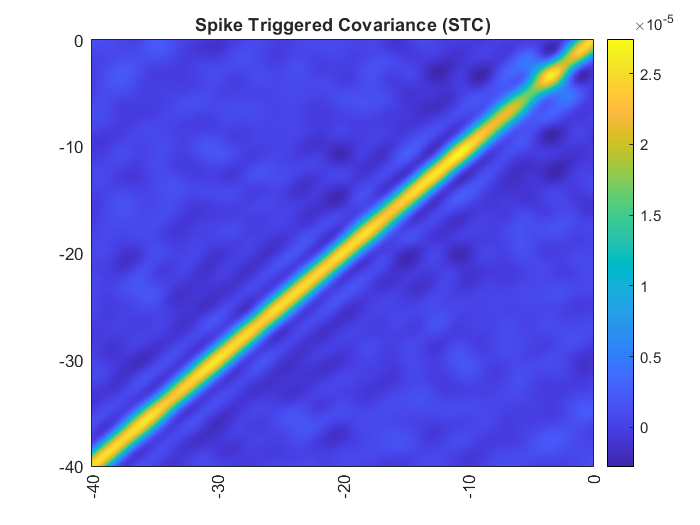


cov_matrix = cov((all_spike_triggers-STA));
nspikes = size(all_spike_triggers,1);
% cov_matrix = (1/(nspikes -1))*(all_spike_triggers-STA)'*(all_spike_triggers-STA);
% cov_matrix = (1/(nspikes -1))*((all_spike_triggers'*all_spike_triggers)-(STA'*STA));

figure;

h = heatmap((cov_matrix), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Spike Triggered Covariance (STC)");

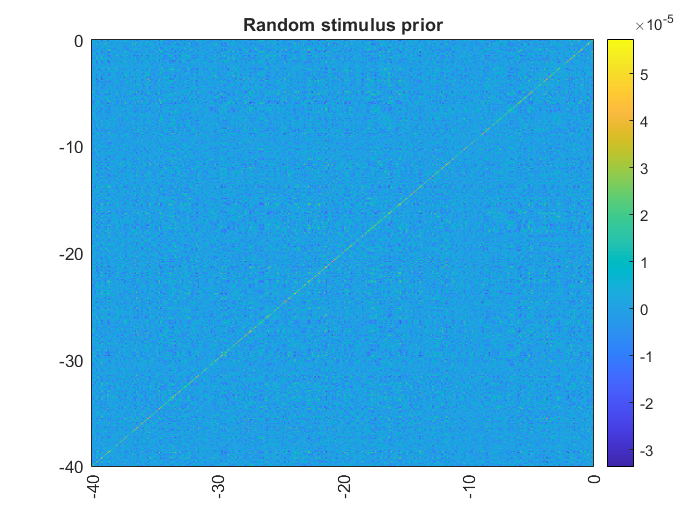

pattern_length = size(all_spike_triggers,2);
nrand_stim = floor(length(stimulus(1,:))/pattern_length);
stimulus_prior = reshape(stimulus(1,1:nrand_stim*pattern_length), [nrand_stim,pattern_length]);
[m,n] = size(stimulus_prior);
% stimulus_prior = stimulus_prior(randperm(m),randperm(n));
% stimulus_prior = all_spike_triggers(randperm(m),randperm(n));
avg_stim = mean(stimulus_prior,1);
stim_prior_cov = cov(stimulus_prior);
% stim_prior_cov = (1/(m -1))*(stimulus_prior')*(stimulus_prior);
figure;
h = heatmap((stim_prior_cov), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Random stimulus prior");

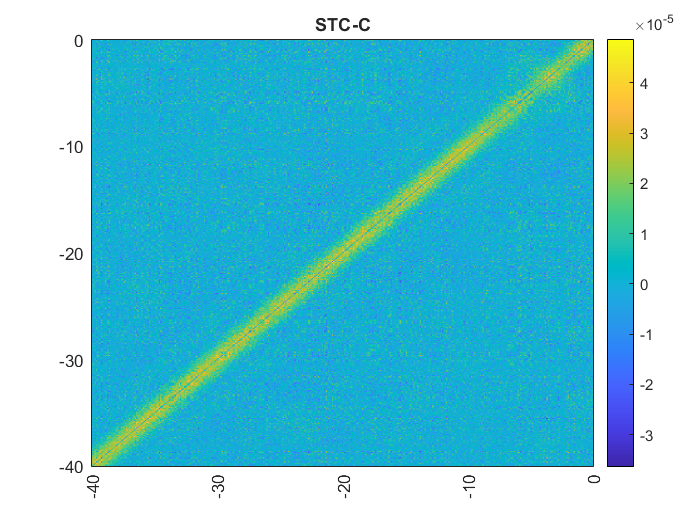

diff_cov = (cov_matrix - stim_prior_cov) ; 
figure;
h = heatmap(diff_cov, 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("STC-C");

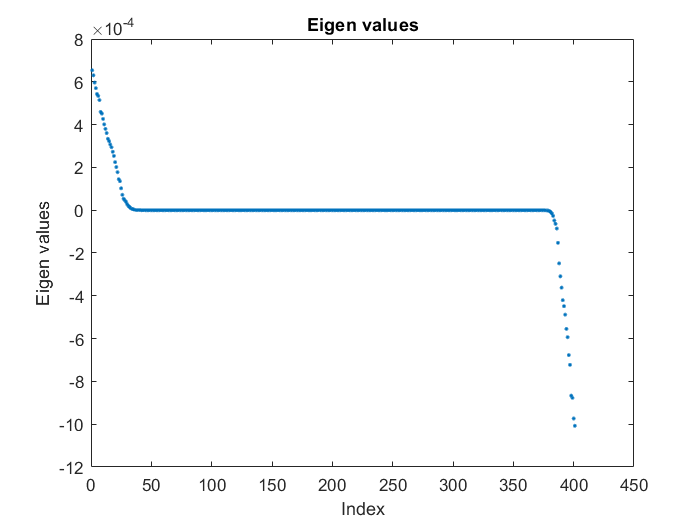


[V,D] = eig(diff_cov);

[~, ind] = sort(diag(D), 'descend');
Ds = D(ind,ind);
Vs = V(:,ind);

figure;
plot(diag(Ds), '.');
title('Eigen values');
ylabel('Eigen values');
xlabel('Index');

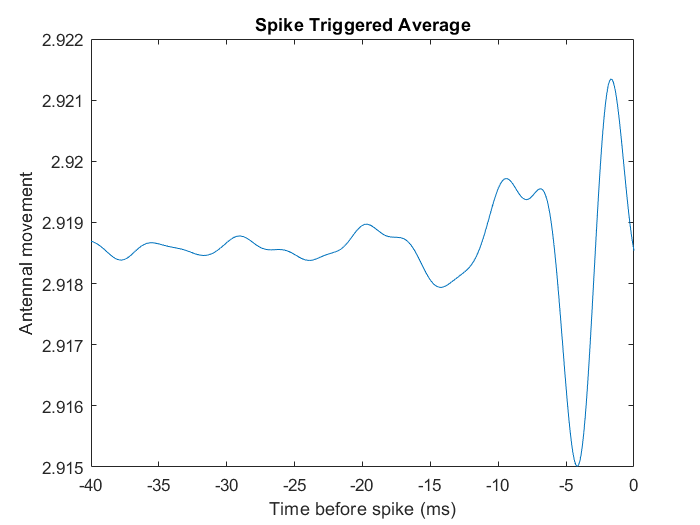


t= linspace(-window*1000, 0, length(STA));

figure;
plot(t, STA);
title('Spike Triggered Average');
xlabel('Time before spike (ms)');
ylabel('Antennal movement');

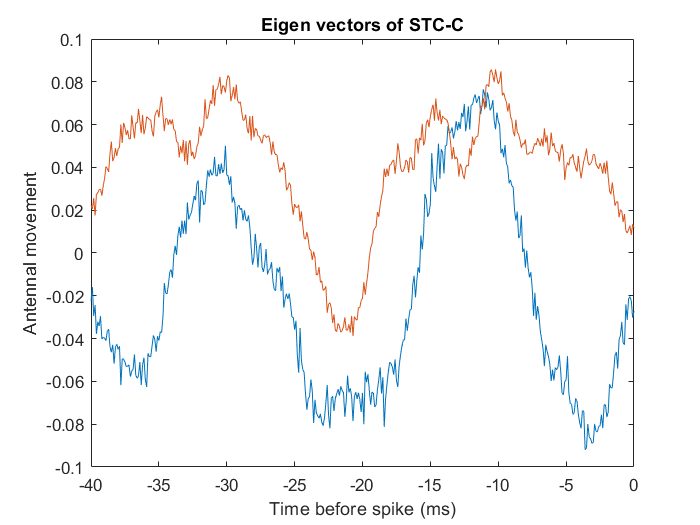

plot(t, Vs(:,1:2));
% legend("STA","EV1","EV2");
title('Eigen vectors of STC-C');
xlabel('Time before spike (ms)');
ylabel('Antennal movement');

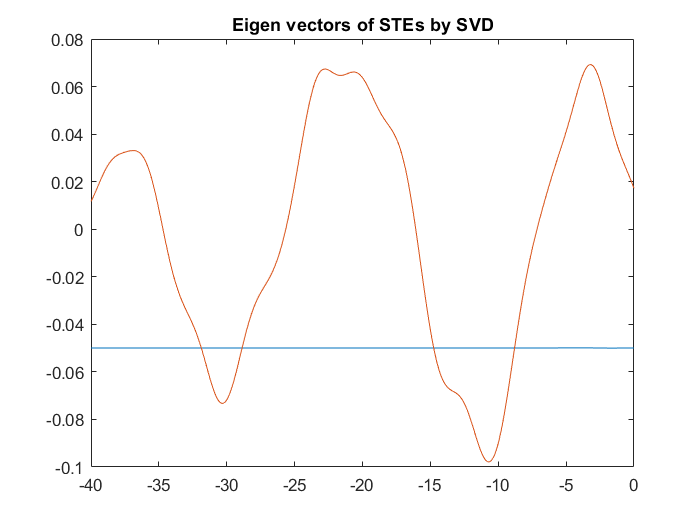


[U,S,W] = svd(all_spike_triggers', 'econ');
D = diag(S);

figure;
plot(t, U(:,1:2));
title('Eigen vectors of STEs by SVD');


% figure;
% plot(t, U(:,1).*D(1).*W(1,:)', t, U(:,2).*D(2).*W(2,:)');